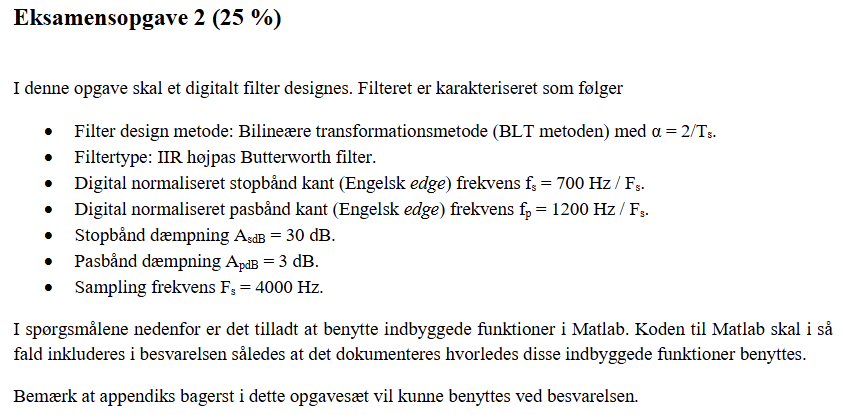

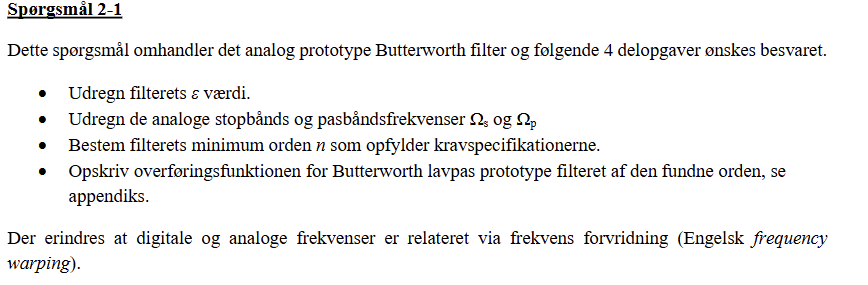

clear
%IIR højpass butter 
Fs = 4000; 
Ts = 1/Fs; 
fs = 700/Fs;
fp = 1200/Fs;
AsdB = 30;
ApdB = 3; 

%vi finder epsilon 
epsilon_i_anden = 10^(0.1*ApdB)-1;

epsilon = sqrt(epsilon_i_anden) 

epsilon = 0.9976


%epsilon = 0.9976 ---- resultat ---- 

%vi finder ws og wp som er de digitale angulære frekvenser 
ws = fs*2*pi;
wp = fp*2*pi;

%vi udregner de analoge vinkelfrekvenser: 
Os = (2/Ts)*tan((ws)/2)

Os = 4.9024e+03

Op= (2/Ts)*tan(wp/2)

Op = 1.1011e+04



new = Op/Os

new = 2.2461



%n_test skal være mindre eller lig med n 
n_test = (log10( (  (10^(0.1*AsdB))-1 )    / ((epsilon_i_anden) )))  /( 2*log10(new))

n_test = 4.2707


n = ceil(n_test)

n = 5


% vi skal bruge et 5 ordens filter 

b = [1];
a = [1,3.2361,5.2361,5.2361,3.2361,1]

a =     1.0000    3.2361    5.2361    5.2361    3.2361    1.0000



H_ana = tf(b,a)


H_ana =
 
                            1
  -----------------------------------------------------
  s^5 + 3.236 s^4 + 5.236 s^3 + 5.236 s^2 + 3.236 s + 1
 
Continuous-time transfer function.



%-------------------------------------------------------------------%
%                                    1
% H_ana(z) =  -----------------------------------------------------
%            s^5 + 3.236 s^4 + 5.236 s^3 + 5.236 s^2 + 3.236 s + 1
%-------------------------------------------------------------------%



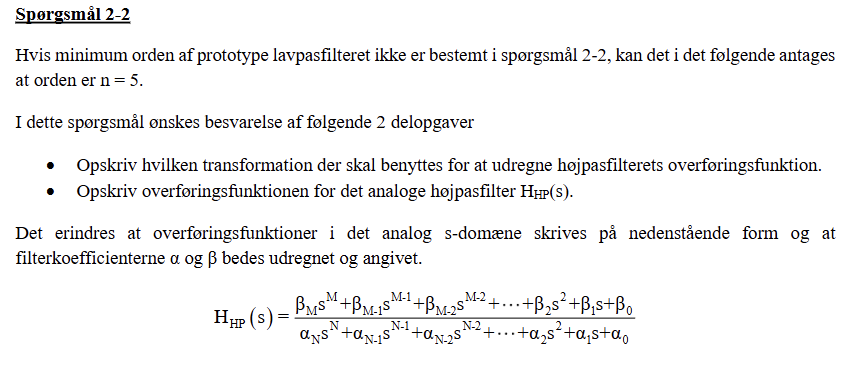

%vi skal benytte transformationen: 
%   s->Omega_pass/s


[num,den] = lp2hp(b,a,Op)

num =     1.0000         0    0.0000         0         0         0


den = 1.0e+20 *

    0.0000    0.0000    0.0000    0.0000    0.0005    1.6186



Ana_Hpass = tf(num,den)


Ana_Hpass =
 
                            s^5 + 1.133e-07 s^3
  -----------------------------------------------------------------------
  s^5 + 3.563e04 s^4 + 6.348e08 s^3 + 6.99e12 s^2 + 4.757e16 s + 1.619e20
 
Continuous-time transfer function.






%                                s^5 + 1.133e-07 s^3
% H_Hpass =  -----------------------------------------------------------------------
%            s^5 + 3.563e04 s^4 + 6.348e08 s^3 + 6.99e12 s^2 + 4.757e16 s + 1.619e20




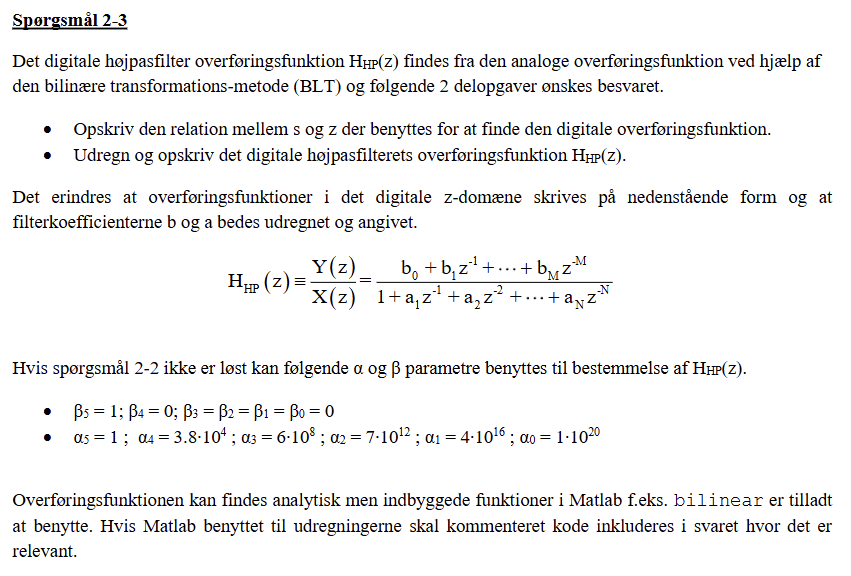

% relationen = (2/Ts)*((z-1)/(z+1))

[numdig,dendig] = bilinear(num,den,Fs);


HHP_dig = tf(numdig,dendig)


HHP_dig =
 
  0.02194 s^5 - 0.1097 s^4 + 0.2194 s^3 - 0.2194 s^2 + 0.1097 s - 0.02194
  -----------------------------------------------------------------------
      s^5 + 0.9853 s^4 + 0.9738 s^3 + 0.3863 s^2 + 0.1112 s + 0.01126
 
Continuous-time transfer function.



%            0.02194 s^5 - 0.1097 s^4 + 0.2194 s^3 - 0.2194 s^2 + 0.1097 s - 0.02194
% HHp_dig =  -----------------------------------------------------------------------
%               s^5 + 0.9853 s^4 + 0.9738 s^3 + 0.3863 s^2 + 0.1112 s + 0.01126



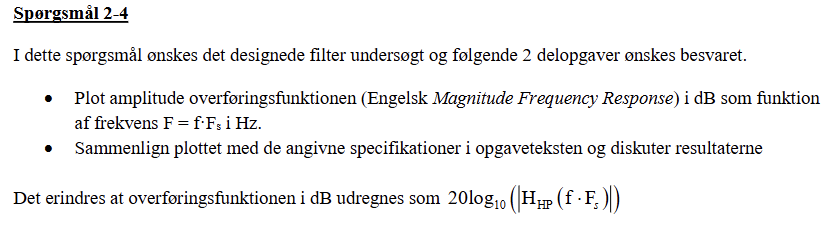

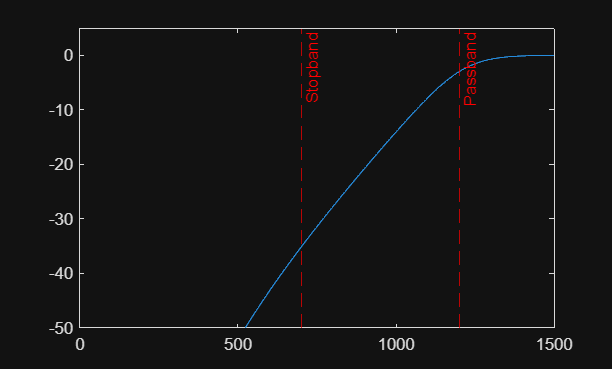

[HP,digfreq] = freqz(numdig,dendig,1024,Fs);

plot(digfreq,20*log10(abs(HP)))
xline(fs*Fs,'--r', "Stopband") % indsætter en linje for stopbåndsfrek 
xline(fp*Fs,'--r', "Passband") % indsætter en linje for passbåndsfrek 

xlim([0,1500]);
ylim([-50,5])


% det passer sgu meget godt

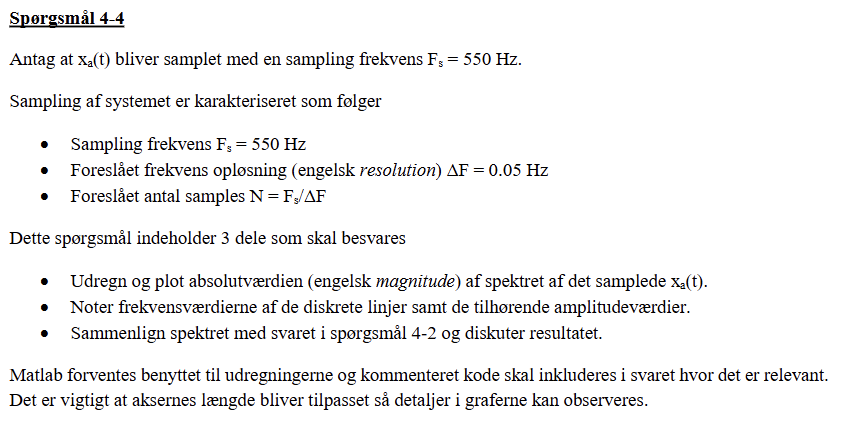

clear
Fs = 550; 
Ts = 1/Fs; 
F1 = 100; 
F2 = 175;
F3 = 200; 
deltaF = 0.05; 
N = Fs/deltaF; 

t = (0:N-1)*Ts;
%n = [-N/2:1:(N/2)-1]

xat = cos(2*pi*F1*t).*(4+cos(2*pi*F2*t))-2*cos(2*pi*F3*t);

XAN = fftshift(fft(xat));
%disse 2 kan begge bruges 
fh = ((-N/2:N/2-1)/N);
fhz = fh*Fs

fhz =  -275.0000 -274.9500 -274.9000 -274.8500 -274.8000 -274.7500 -274.7000 -274.6500 -274.6000 -274.5500 -274.5000 -274.4500 -274.4000 -274.3500 -274.3000 -274.2500 -274.2000 -274.1500 -274.1000 -274.0500 -274.0000 -273.9500 -273.9000 -273.8500 -273.8000 -273.7500 -273.7000 -273.6500 -273.6000 -273.5500 -273.5000 -273.4500 -273.4000 -273.3500 -273.3000 -273.2500 -273.2000 -273.1500 -273.1000 -273.0500 -273.0000 -272.9500 -272.9000 -272.8500 -272.8000 -272.7500 -272.7000 -272.6500 -272.6000 -272.5500


f = linspace(-Fs/2,Fs/2,N );

n = [-N/2:1:(N/2)-1]

n =        -5500       -5499       -5498       -5497       -5496       -5495       -5494       -5493       -5492       -5491       -5490       -5489       -5488       -5487       -5486       -5485       -5484       -5483       -5482       -5481       -5480       -5479       -5478       -5477       -5476       -5475       -5474       -5473       -5472       -5471       -5470       -5469       -5468       -5467       -5466       -5465       -5464       -5463       -5462       -5461       -5460       -5459       -5458       -5457       -5456       -5455       -5454       -5453       -5452       -5451


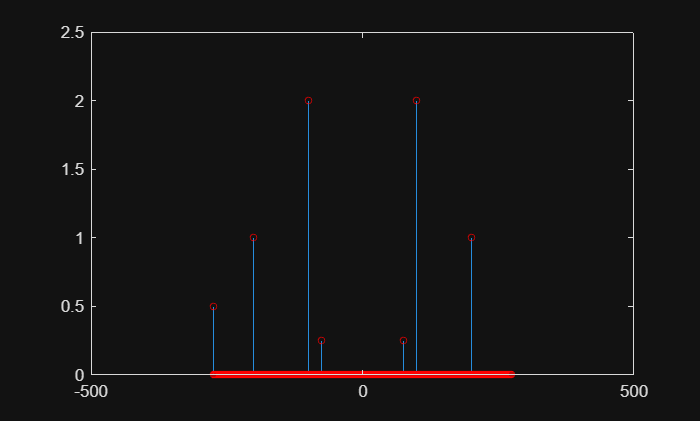

stem(fhz,abs(XAN/N),'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')
xlim([-500,500])
ylim([0,2.5])